# **demo02 of writeMesh**

**Triangular mesh with multiple phases**

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/writeMesh).

## Initialize

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Load mesh

Let's load the mesh data from "mesh_data_2.mat"

load("mesh_data_2.mat")

We will see 3 variables.

vert

vert =     0.5000    0.5000
    0.5000   23.5000
    0.5000   69.5000
    0.5000   92.5000
    3.5000   25.5000
    6.1700   24.9100
    6.8100   79.8900
    9.2600   88.7400
    9.5000  100.5000
   14.2400   60.3300


ele

ele =    217   102   219
   226   202   217
   228   165   229
   226   217   219
   245   246   215
   221   152    19
   241   183   181
   162    65   160
   251   239   243
   243   190   192


tnum

tnum =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


Check the number of phase in the mesh

length(unique(tnum))

ans = 2

## Plot mesh

Use function plotMeshes to plot mesh.

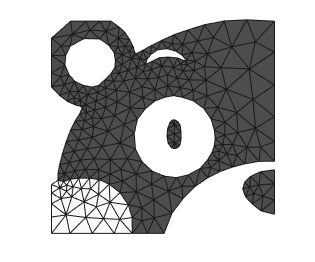

plotMeshes(vert,ele,tnum);

We saw 2 phases in the mesh.

## Export as inp file (Abaqus)

We use function printInp2d to write 2d mesh to inp file.

The exported inp file would have a model with one part, which contains 2 sections. Each section corresponds to one phase in the mesh.

We can specify element type, precision_nodecoor and file name.

ele_type = 'CPS3';
precision_nodecoor = 8;
file_name = 'test.inp';

printInp2d( vert, ele, tnum, ele_type, precision_nodecoor, file_name );

printInp2d Done! Check the inp file!


## Export as bdf file (Nastran bulk data)

We use function printBdf2d to write 2d mesh to bdf file.

precision_nodecoor = 8;
file_name = 'test.bdf';

printBdf2d( vert, ele, tnum, [], precision_nodecoor, file_name );

printBdf2d Done! Check the bdf file!


## Export as msh file (Gmsh mesh file)

We use function printMsh to write 2d mesh to msh file.

precision_nodecoor = 8;
file_name = 'test.msh';

printMsh( vert, ele, tnum, [], precision_nodecoor, file_name );

printMsh Done! Check the msh file!


When we open 'test.msh' in Gmsh, we can see 2 physical surfaces, which corresponds to 2 phases in our mesh.

BTW, we will see 4 surfaces in Gmsh. Note that, in Gmsh, surface and physical surface are different concepts. Gmsh use surfaces to define physical surface. Check Gmsh manual.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo